# Spider

**Overview**

The `Spider` chart manages the display of data measuring several distinct numeric variables recorded from one or more subjects. The chart backdrop is a "web" comprising a series of concentric regular polygons and angular rays.

The chart data comprises a numeric matrix `Data` of size $p\times q$, where:

- $p$ is the number of numeric variables (equal to the number of vertices and edges in the polygons),

- $q$ is the number of subjects (equal to the number of data lines on the chart).

Each row of the chart data represents a variable, and each column represents a complete set of measurements for one subject. Each measured value lies between 0 and 1, which allows distinct variables to be compared easily. To display measured values not lying in the range $[0, 1]$, the input data matrix should be rescaled on a columnwise basis. For ease of comparison, the chart backdrop has 10 concentric polygons with radii $r=0.1, 0.2, \dots, 0.9, 1$.

We impose the constraint $3\leq p\leq 20$ on the number of variables. The lower bound $p\geq 3$ ensures that the chart backdrop has at least 3 nodes, i.e., that the web is at least triangular. The upper bound $p\leq 20$ is purely for visual reasons and ensures that the chart backdrop has at most 20 nodes and does not become too cluttered. There is no restriction on the number of lines $q$, but in practice the chart becomes tricky to read if $q$ is too large.

There is also an additional chart data property `TargetData` of size $p\times 1$. These values are plotted on the web using a separate line object, which can be toggled on or off as required. Visualizing the `TargetData` property allows the observed data measurements to be compared against their target values. As above, the target data should lie in the range $[0, 1]$.

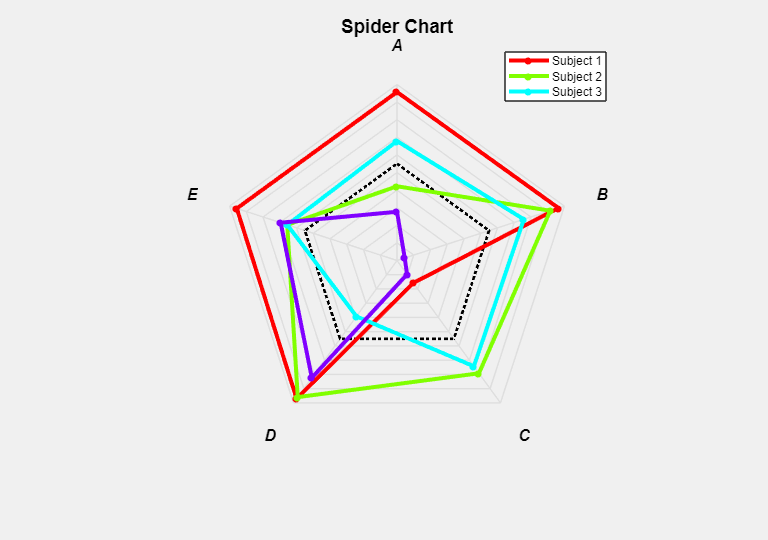

**Resources**

[Open](matlab: edit(fullfile(catalogRoot(), "+example", "Spider.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot(), "+chart", "Spider.m"))) the source code for the `Spider` chart.

## Generate sample chart data for one subject.

Let's start with one subject and assume that there are five measured variables.

rng( "default" )
data = rand( 5, 1 );

Define the node labels.

labels = "Property " + (1:length( data ));

## Create a figure for the chart.

f = exampleFigure( "Name", "Spider Example" );

## Create the chart.

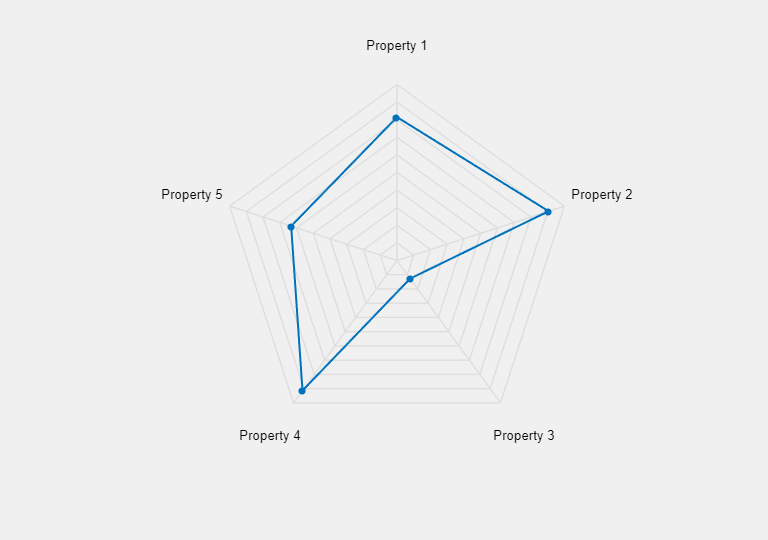

SP = chart.Spider( "Parent", f, ...
    "Data", data, ...
    "LabelText", labels );

## Annotate the chart.

The `Spider` chart has the `title` and `legend` methods for annotation.

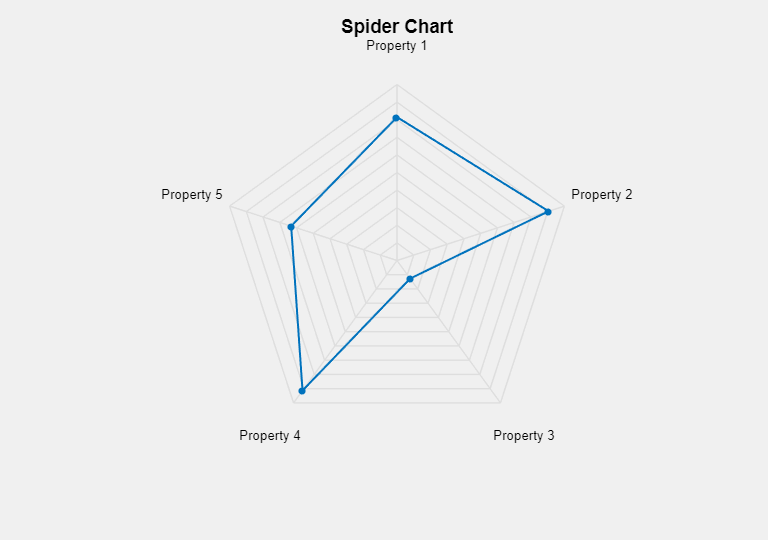

title( SP, "Spider Chart", "FontSize", 14 )

## Add target data and customize the appearance of the target line.

We can add a target data vector to the chart.

SP.TargetData = 0.35 * ones( SP.NumNodes, 1 );

Customize the appearance of the target line.

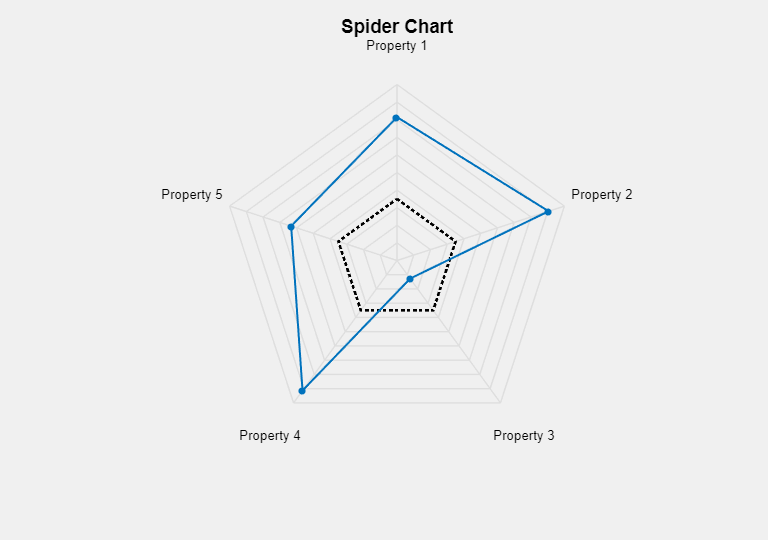

set( SP, "TargetVisible", "on", "TargetLineWidth", 2 )

## Hide the target line.

SP.TargetVisible = "off";

## Decrease the number of observed variables.

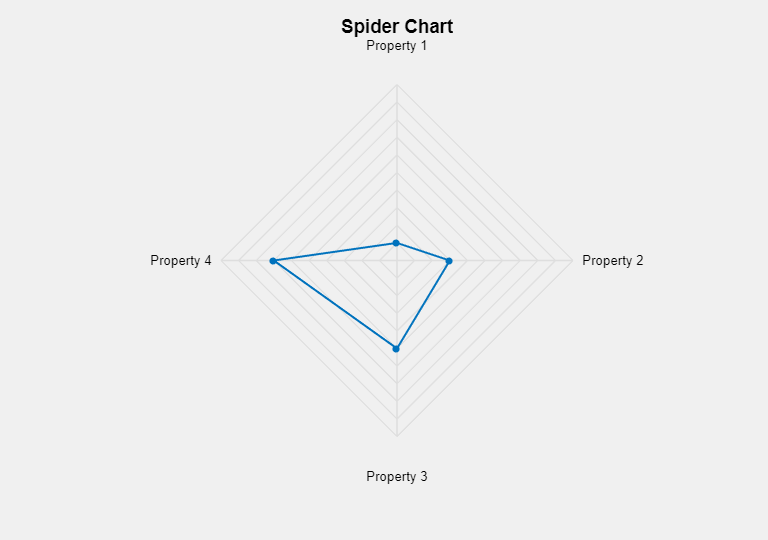

SP.Data = [0.1; 0.3; 0.5; 0.7];

## Increase the number of observed variables.

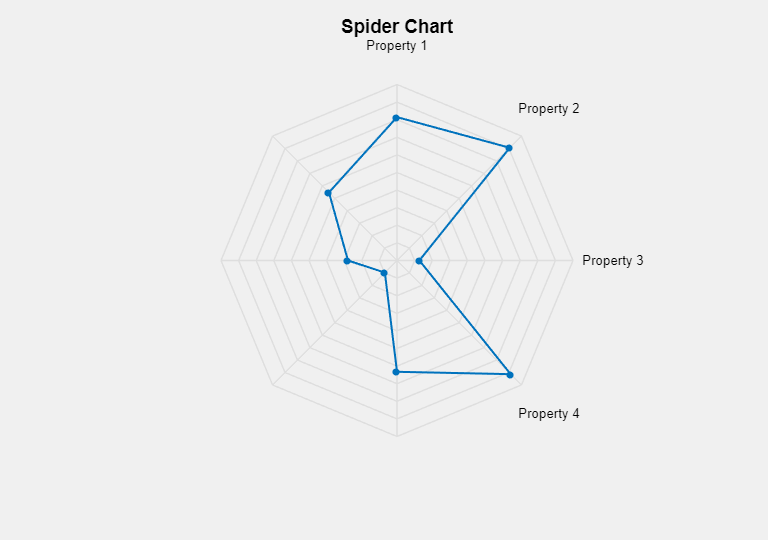

rng( "default" )
SP.Data = rand( 8, 1 );

## Update the labels.

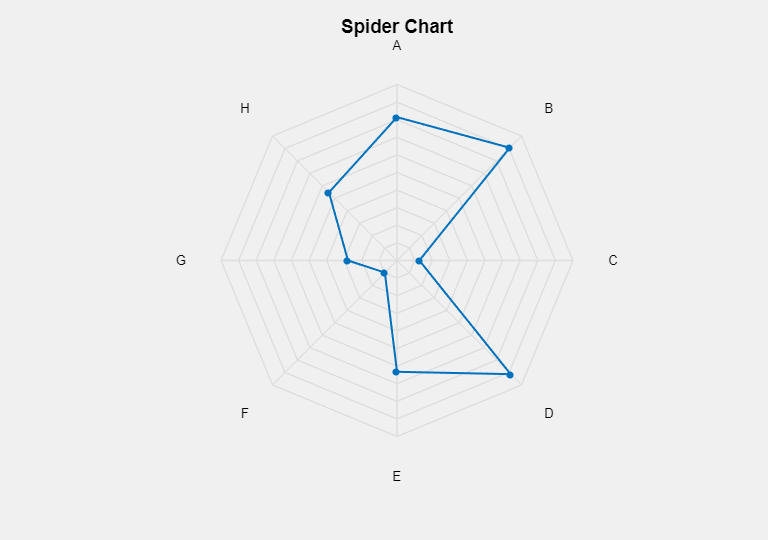

SP.LabelText = ["A", "B", "C", "D", "E", "F", "G", "H"];

## Increase the number of subjects.

The number of subjects is defined by the number of columns in the chart data matrix.

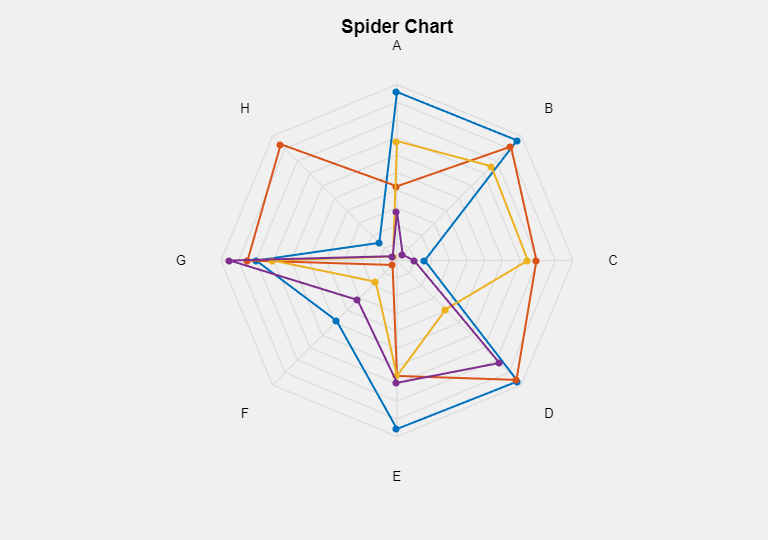

SP.Data = rand( 8, 4 );

## Decrease the number of observed variables.

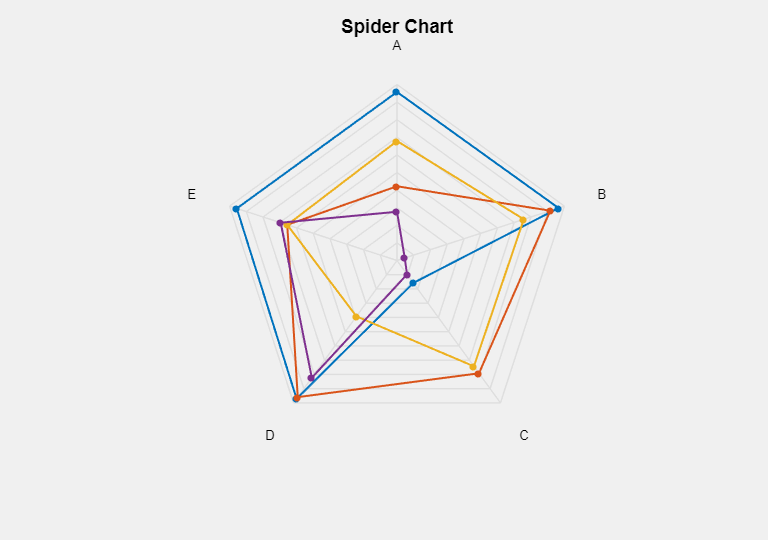

SP.Data = SP.Data(1:5, :);

## Add a legend.

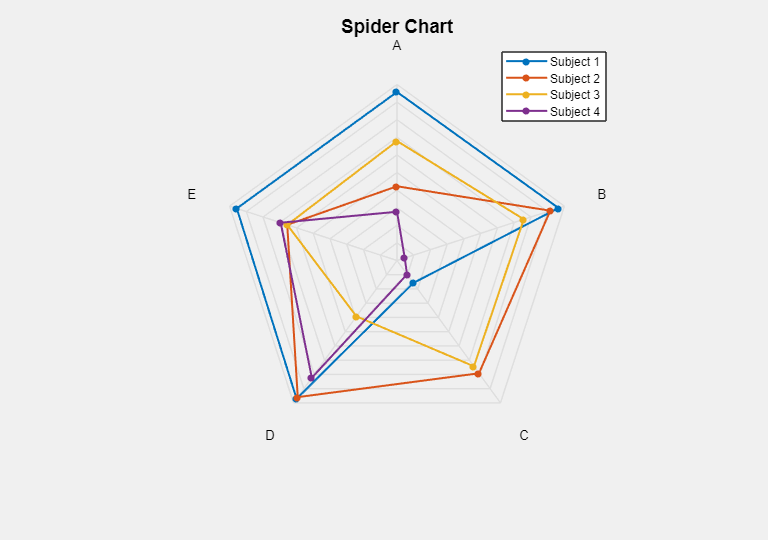

drawnow()
legend( SP, "Subject " + (1:SP.NumLines) )

## Update the target data.

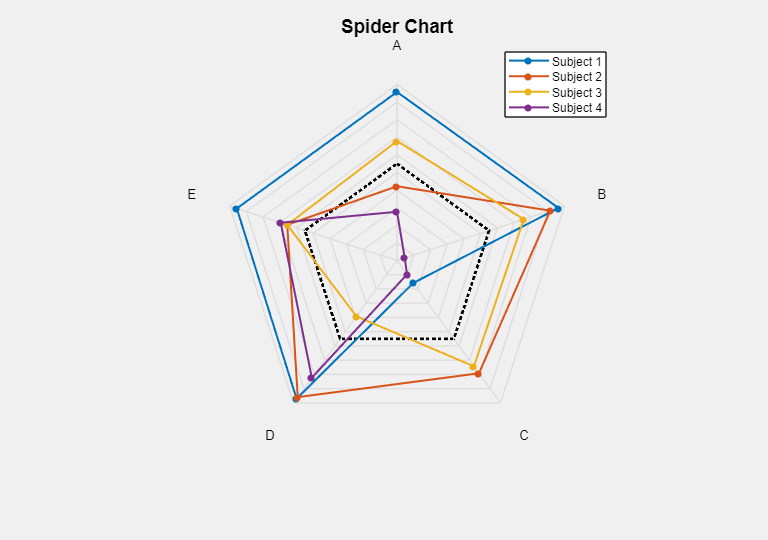

set( SP, "TargetData", 0.55 * ones( SP.NumNodes, 1 ), ...
    "TargetVisible", "on" )

## Customize the visual appearance of the chart.

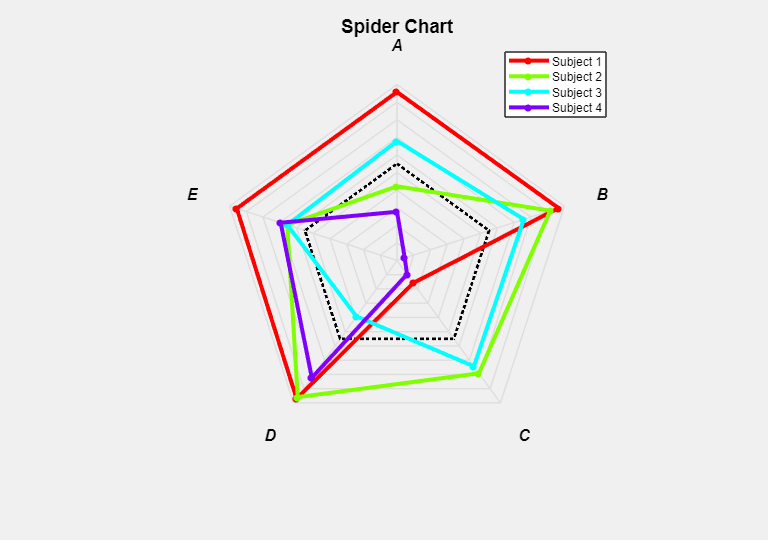

drawnow()
set( SP, "LineColors", hsv( SP.NumLines ), ...
    "LineWidth", 3, ...
    "LabelFontWeight", "bold", ...
    "LabelFontSize", 12, ...
    "LabelFontAngle", "italic" )

*Copyright 2019-2021 The MathWorks, Inc.*